## **Understanding CIC Compensation Filters**

ALTERA Application Note 455

#### At first, set the CIC filter parameters:

R = 4; %% Decimation factor
M = 1; %% Differential delay
N = 8; %% Number of stages
B = 16; %% Coeffi. Bit-width
Fs = 91.392e6; %% (High) Sampling freq in Hz before decimation
Fc = 4.85e6; %% Pass band edge in Hz
%%%%%%% fir2.m parameters %%%%%%
L = 110; %% Filter order; must be even
Fo = R*Fc/Fs; %% Normalized Cutoff freq; 0<Fo<=0.5/M;
% Fo = 0.5/M; %% use Fo=0.5 if you don't care responses are


#### and buld the CIC filter:

cicdecim = dsp.CICDecimator(...
    'DecimationFactor',R,...
    'NumSections',N);
decimcasc = dsp.FilterCascade(cicdecim,...
    1/gain(cicdecim));


#### then create the FIR filter compensating the CIC filter, using dsp.fir2:

 b = firceqrip(200,0.25,[0.02 10e-7],'invsinc',[1 1.7]);

#### and build it:

fircomp_gain = dsp.FIRFilter(b);
fircomp = dsp.FilterCascade(fircomp_gain, 1/sum(b));


#### Finally create the CIC + FIR filter:

% Create the CIC + FIR filter
cicfir = dsp.FilterCascade(decimcasc, fircomp);


#### Show the three filters:

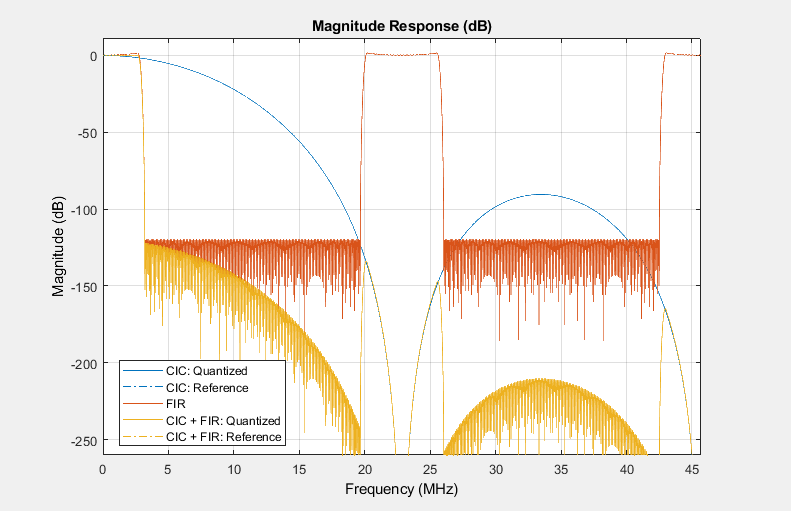

% view the three filters
myfv = fvtool(decimcasc, fircomp, cicfir, 'Fs', [Fs, Fs/R, Fs]);
legend(myfv, "CIC", "FIR", "CIC + FIR");  